1 + 1

ans = 2

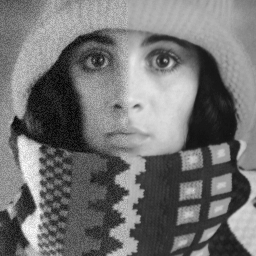

I = readim('truinoise.tif');

dipshow(I);
f = gcf;
f.Name = 'Original image';
f.NumberTitle = 'off';

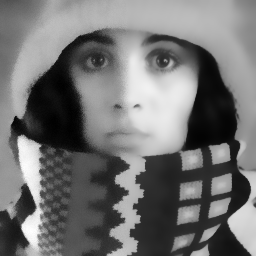


I = double(im2mat(I));
tonalSigma = 50;
spatialSigma = 5;

in = bilateral(I, tonalSigma, spatialSigma);

dipshow(mat2im(in),'lin')
f = gcf;
f.Name = 'Filtered image';
f.NumberTitle = 'off';